# **Vision Artificial. GIEC.**

# **	Sistemas de Vision Artificial. GIC.**

**	Miguel Angel Garcia, Juan Manuel Miguel, Sira Palazuelos. **

**  Departamento de Electrónica. Universidad de Alcalá.**

# Tema 5: ejercicio 02 - k-Nearest Neighbour (kNN)

clc;
clear all;
close all;

La base de datos `hospital` se ha dividido en dos grupos: 50% para entrenamiento y 50% para test.

Step 1) Carga datos

% base de datos 
load hospital;

% se utiliza solo la presión sanguinea
data = [hospital.BloodPressure]; 

% se clasifican los datos como 1 si es fumador y 0 si no lo es
HS = categorical(hospital.Smoker, [1 0], {'Smoker' 'Non-Smoker'});

rng(2) % control de números aleatorios

% se obtienen una distribución aleatoria de los índices del tamaño de los datos
idx = randperm(length(data))';

% 50% para entrenamiento y 50% para test
distribution_train = 0.5;
idx_train = idx(1:length(data)*distribution_train);
idx_test = idx(length(data)*distribution_train+1:length(data));

% valores y etiquetas para entrenamiento
data_train = data(idx_train, :);
label_train = HS(idx_train); % 'Smoker' = 1, 'Non-Smoker' = 0

tabulate(label_train)

       Value    Count   Percent
      Smoker       17     34.00%
  Non-Smoker       33     66.00%


% valores y etiquetas para test
data_test = data(idx_test, :);
label_test = HS(idx_test); % 'Smoker' = 1, 'Non-Smoker' = 0

tabulate(label_test)

       Value    Count   Percent
      Smoker       17     34.00%
  Non-Smoker       33     66.00%


Step 2) Visualiza los datos usando un gráfico de dispersión

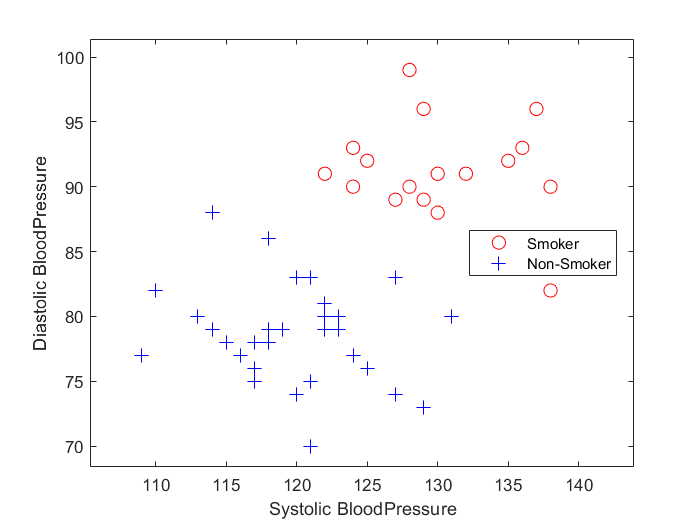

gscatter(data_train(:,1), data_train(:,2), label_train, 'rb', 'o+', 8, 'on')
xlabel('Systolic BloodPressure');
ylabel('Diastolic BloodPressure');
legend('Location', 'best');

Step 3) Entrenamiento del modelo

k = 1;
Model_kNN = fitcknn(data_train, label_train, 'NumNeighbors', k);

Se pide:

         1. El código (CODE 1) dibuja la supercie de decisión utilizando del modelo entrenado. Obtenga la predicción del conjunto de datos de test usando la función: `predict() `y dibuje los resultados de la supercie de decisión que se ha creado con el código anterior.

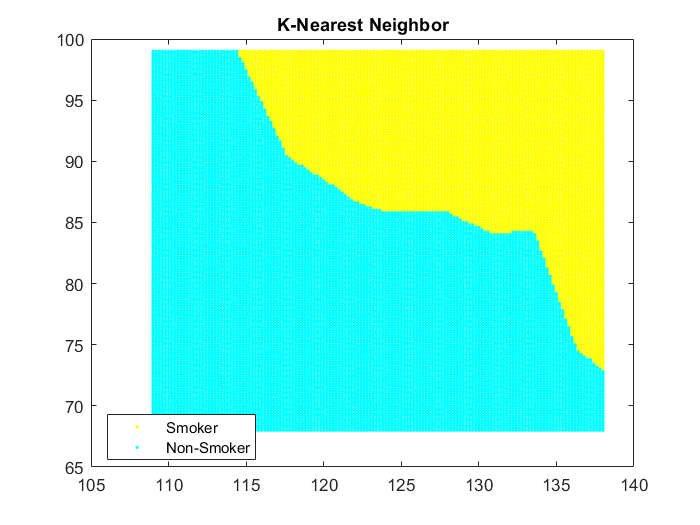

% mesh
mesh_step = 0.2;
x1range = min(data(:,1)) : mesh_step : max(data(:,1));
x2range = min(data(:,2)) : mesh_step : max(data(:,2));
[xx1, xx2] = meshgrid(x1range, x2range);
mesh = [xx1(:) xx2(:)];

% predicción
predictions_mesh = predict(Model_kNN, mesh);

% superficie de decisión
gscatter(xx1(:), xx2(:), predictions_mesh, 'yc');
title('K-Nearest Neighbor')

**La diferencia entre realizar una predicción de este modelo y el de test es que en el modelo de test se tienen las etiquetas de si son fumadores o no.a**

         2. Calcule la matriz de confusión de los datos de test que se han obtenido con el Model_kNN`,` utilizando la función `confusionmat.` Si lo desea puede mostrarla gráficamente con la función `confusionchart`.

label_prediction = predict(Model_kNN, data_test);
confusion_mat = confusionmat(label_test, label_prediction) % compara los valores verdaderos con las predicciones

confusion_mat =     12     5
     2    31


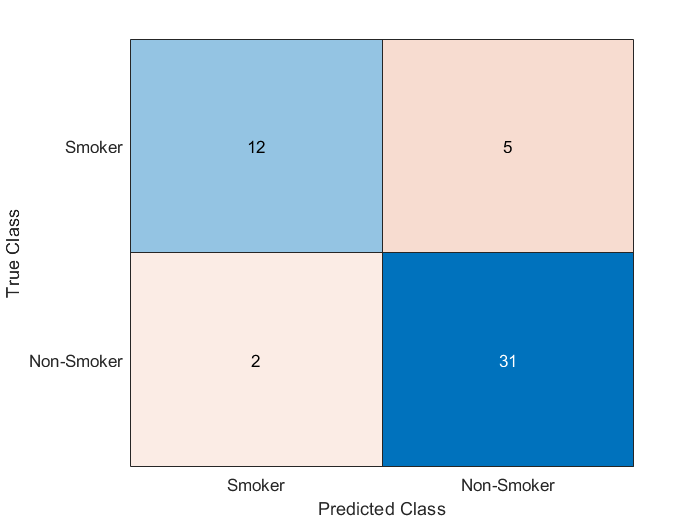

confusion_chart = confusionchart(label_test, label_prediction);

**Como se puede observar, el modelo **

         3. Calcule la especificidad y sensibilidad como: `especificidad = TN/(TN+FP)` y `sensibilidad = TP/(TP+FN)`, considerando como clase positiva (`P`) los fumadores (`'Smoke'`). Nota: Estos parámetros sólo se pueden calcular para clasificadores binarios.

         4. Cambie el número `k` del vecino más cercano (`'NumNeighbors'`) en el paso 3 utilizando los siguientes valores `K = 1, 5, 10 `y compruebe cómo afecta a  la especificidad y sensibilidad del clasificador.

         5. Entrene de nuevo utilizando el modelo naive Bayes utilizando la función  `fitcnb()`. Compare los resultados oobtenidos con el clasificador anterior, kNN.